# Comparing Controller with all Patients from Jost

This just puts the code from comparison_individual.mlx in a for loop (not really important)

clear all;
clc; 
close all; 

DataSheet1 = readmatrix("Data Sheet 1.csv");
DataSheet2 = readmatrix("Data Sheet 2.csv");

total_patients = DataSheet2(end, 1);
% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.05;

lower = 1; upper = 2;
var_w = 0.025;

% population parameters (from Jost et al.)
population_params = [2.06; 0.146; 0.103; 0.866];

N_cyclespred = 5;
n_params = length(population_params);

% for exporting figures
root = fileparts(matlab.desktop.editor.getActiveFilename);
new_folder = sprintf("%s\\patient_comparisons_a", root);
mkdir(new_folder);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


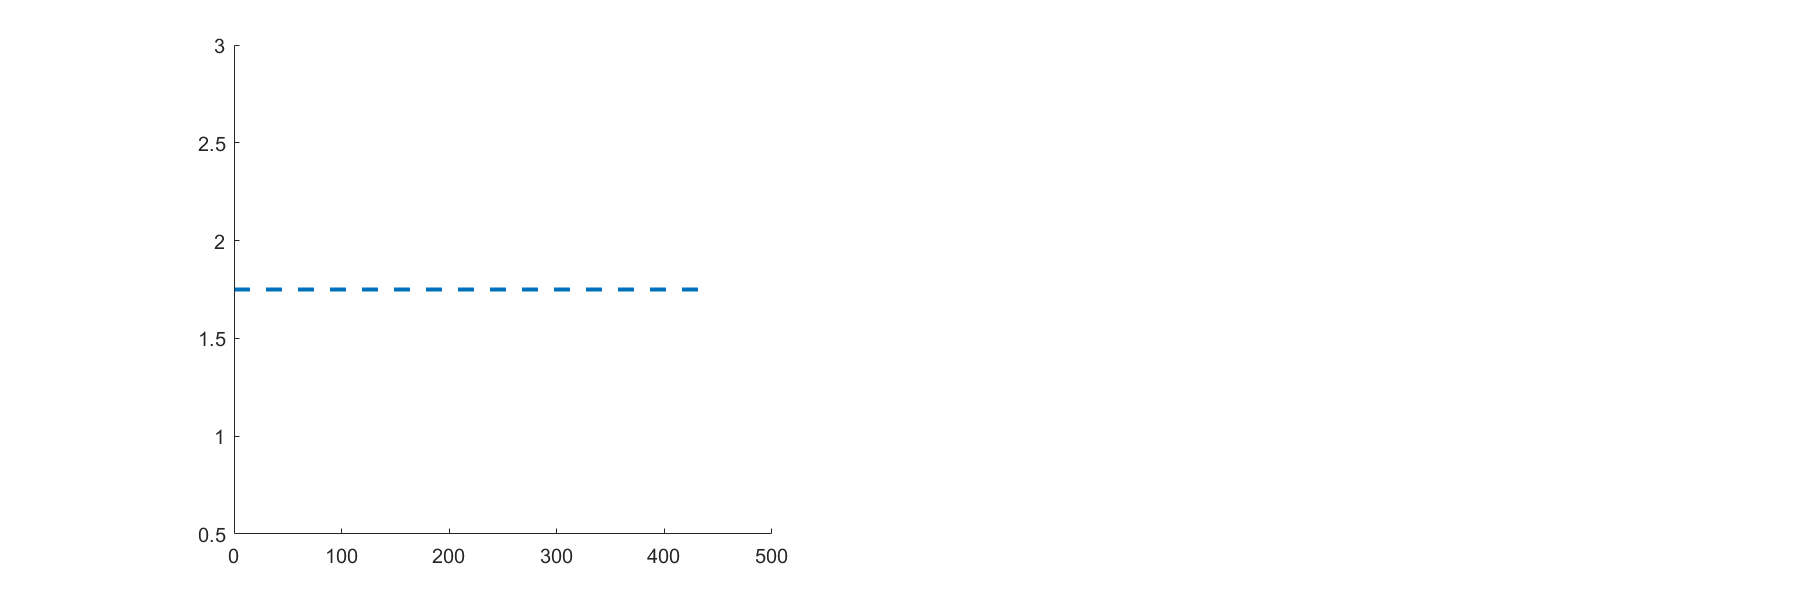

Error using plot
Vectors must be the same length.

for patientID = 2:10
    
    p_actual = DataSheet1(patientID, 2:5)';
    p_guess = population_params;
    
    patient_data    = [];
    patient_doses   = [];
    patient_evid    = [];
    patient_cycles  = [];
    simulation_time = [];
    cycle_start_time = 10000; % can be arbitrary because will be overwritten
    last_measurement = true;
    treatment_end_time = -1;
    
    for k=1:length(DataSheet2)
        patient_id  = DataSheet2(k,1);
        time        = DataSheet2(k,2);
        measurement = DataSheet2(k,3);
        dose        = DataSheet2(k,5);
        evid        = DataSheet2(k,7);
        
        if patient_id - 100 == patientID
            bsa = DataSheet2(k,11);
            if measurement ~= 0
                patient_data = [patient_data; time measurement];
                if last_measurement == false
                    patient_cycles = [...
                        patient_cycles;...
                        cycle_start_time ...
                        prev_time ...
                        round(abs(prev_time - cycle_start_time) + 1)];
                    last_measurement = true;
                end
            else
                if last_measurement == true
                    cycle_start_time = time;
                    last_measurement = false;
                end
            end
            if evid
                patient_doses = [patient_doses; time dose];
            end
            patient_evid = [patient_evid; time evid];
            simulation_time = [simulation_time; time];
            treatment_end_time = time;
        end
        
        prev_time = time;
    end

    clear population_bsa population_params_guess population_params
    clear patient_id time measurement dose evid

    % Initialization
    theta_10_init = 2.3765;
    x0 = calc_init_state(patient_data(1,2), p_guess(2), theta_10_init);
    lb_drug = 0.01;
    ub_drug = 50*bsa*2; % note: this is twice the optimal dosing quantity

    % Simulation length based on time vector
    t_s = step_size; % units in days
    start_time = patient_cycles(1,1);
    end_time = patient_cycles(end,2);
    N_days = round(abs(start_time-end_time));
    N_cycles = size(patient_cycles,1);
    N_steps = round(N_days / t_s);
    N_steps_per_day = 1 / t_s;
    time = (start_time:t_s:end_time + t_s);

    % Nominal Trajectory
    u_nominal = ones([N_steps 1]) * 50 * bsa; % nominal trajectory for the drug (6-MP doses)
    rho = ones([N_steps+1 1]) * 1.75; % nominal trajectory for neutrophils is just a setpoint

    % Virtual Patient
    N_cyclespred = 5;
    x_calc = [];
    y_calc = [];
    past_measurements = [];
    params_calc = [];
    u_calc = zeros([1,N_days]);

    x_calc(:,:,1) = x0;
    y_calc(:,:,1) = g_nonlin(x0);
    params_calc(:,:,1) = p_guess;
    past_measurements(:,:,1) = [y_calc(:,:,1); 1; patient_data(1,1)];

    cycle = 1;
    k = 0;

    while k < N_days && cycle <= N_cycles
        prev_step = size(x_calc,3);  
        N_cycledays = patient_cycles(cycle,3);
        N_drugdays = N_cycledays;
        
        % x0_estimate = calc_init_state(params_calc(1,1,cycle), params_calc(2,1,cycle), theta_10_init);
        f = @(p)calc_params_comparison(past_measurements, p, x0, u_calc, prev_step, N_cycledays, N_cycledays, t_s);
        [p_star, fval] = fmincon(...
            f,params_calc(:,:,cycle), [], [], [], [], ...
            repmat(0.001, [size(params_calc, 1) 1]), ...
            repmat(5.00, [size(params_calc, 1) 1]) ...
        );
        
        g = @(u)calc_control_comparison(...
            p_star, rho, x_calc(:,:,prev_step), k, cycle, u, 10, 0.0001, ...
            N_cyclespred, N_cyclespred, patient_cycles, t_s ...
        );
    
        init_guess_u = 50*bsa;
        [u_star, gval] = fmincon(...
            g,repmat(init_guess_u, [N_cyclespred 1]), [], [], [], [], ...
            repmat(lb_drug, [N_cyclespred 1]), ...
            repmat(ub_drug, [N_cyclespred 1]) ...
        );
        
        u_calc(k+1:k+N_drugdays) = u_star(1);
        params_calc(:,:,cycle+1) = p_star;

        for i=prev_step:prev_step + N_steps_per_day*N_cycledays - 1
            x_calc(:,:,i+1) = jost_discrete((i+1)*t_s,x_calc(:,:,i), u_calc(k+1),p_actual,N_cycledays,N_drugdays,t_s);
            y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
            
            if size(past_measurements,3) < cycle+1
                time_diff = patient_data(cycle+1,1) - time(:,i+1);
                if time_diff < 0
                    past_measurements(:,:,end+1) = [y_calc(:,:,i); i; time(:,i)];
                end
            end
        end
        
        cycle = cycle + 1;
        k = k + N_cycledays;    
    end

    u_calc_full = zeros(size(u_nominal));
    for k=1:N_days
        i = N_steps_per_day*(k-1);
        u_calc_full(i+1:i+N_steps_per_day,:) = u_calc(k)*(ones(N_steps_per_day,1));
    end
    y_neutrophils = reshape(y_calc(1,1,:),[1 size(y_calc, 3)]);
    p1 = reshape(params_calc(1,1,:),[1 cycle]);
    p2 = reshape(params_calc(2,1,:),[1 cycle]);
    p3 = reshape(params_calc(3,1,:),[1 cycle]);
    p4 = reshape(params_calc(4,1,:),[1 cycle]);

    all_figs = figure("Name", sprintf("All Figures for Patient %d", patientID), "Position", [0,0,1200,400]);
    axes_font_size = 12;
    use_legend = false;
    
    % ------------------------------ NEUTROPHIL PLOT --------------------------------------------
    subplot(1,10,[1 2 3 4])
    hold on
    
    plot(time,rho, "LineStyle","--", "LineWidth", 2)
    plot(time,y_neutrophils, "LineWidth", 2)
    scatter(patient_data(:,1), patient_data(:,2), 30, [0.4660 0.6740 0.1880], "filled")
    scatter(past_measurements(3,:,:), past_measurements(1,:,:), 75, "black", "filled", "pentagram")
    
    yline(2, "-.");
    yline(0.5, "-.");
    xline(patient_cycles(end,2), '-.');
    ylim([0.25 max(patient_data(:,2)) + 0.25])
    
    xlabel('Time (days)', "FontSize", axes_font_size)
    ylabel('ANC (10^9 cells/L blood)', "FontSize", axes_font_size)
    
    if use_legend
        lgd = legend(...
            ' Desired neutrophil concentration',...
            sprintf(' Neutrophil concentration using Jost et al. 2020\n biochemical model and our proof-of-concept controller'),...
            ' Measurements from patient during clinical treatment',...
            ' "Measurements" from virtual patient'...
        );
        lgd.Location = "northoutside";
        lgd.FontSize = 8;
    end
    hold off
    
    % ------------------------------ 6-MP DOSE PLOT --------------------------------------------
    subplot(1,10,[5 6 7])
    hold on
    
    plot(time(:,1:end-1),u_nominal, "LineStyle", "--", "LineWidth", 2)
    plot(time(:,1:end-1),u_calc_full, "LineWidth", 2)
    plot(patient_doses(:,1), patient_doses(:,2), "Color", "#77AC30", "LineWidth", 2)
    
    xlabel('Time (days)', "FontSize", axes_font_size)
    ylabel('6-MP dose (mg/day)', "FontSize", axes_font_size)
    xlim([0 patient_cycles(end,2) + 25])
    
    if use_legend
        l = legend('Anticipated standard dose','Optimized doses','Doses from clinical treatment');
        l.Location = "northoutside";
        l.FontSize = 8;
    end
    hold off
    
    % --------------------------- PARAMETER ESTIMATION PLOT -------------------------------------
    subplot(1,10,[8 9 10])
    hold on
    
    plot(p1, "LineWidth", 2, "Color", "#D95319")
    plot(p2, "LineWidth", 2, "Color", "#A2142F")
    plot(p3, "LineWidth", 2, "Color", "#4DBEEE")
    plot(p4, "LineWidth", 2, "Color", "#7E2F8E")
    
    base_line = yline(p_actual(1), "--", "True \theta_1", "Color", "#D95319", "LineWidth", 1);
    ktr_line = yline(p_actual(2), "--", "True \theta_2", "Color", "#A2142F", "LineWidth", 1);
    slope_line = yline(p_actual(3), "--", "True \theta_3", "Color", "#4DBEEE", "LineWidth", 1);
    gamma_line = yline(p_actual(4), "--", "True \theta_4", "Color", "#7E2F8E", "LineWidth", 1);
    
    ktr_line.LabelVerticalAlignment = "middle";
    
    xlabel('Time (cycles)', "FontSize", axes_font_size)
    ylabel('Parameter Estimation', "FontSize", axes_font_size)
    
    if use_legend
        lgd = legend(...
            sprintf('%s - Neutrophil count baseline', "\theta_1"), ...
            sprintf('%s - Inter-compartmental transfer rate', "\theta_2"), ...
            sprintf('%s - PD effect slope parameter', "\theta_3"), ...
            sprintf('%s - Feedback parameter', "\theta_4") ...
        );
        lgd.Location = "northoutside";
        lgd.FontSize = 8;
    end
    hold off
    
    all_figs_filename = fullfile(new_folder, sprintf("patient%d.png", patientID));
    exportgraphics(all_figs, all_figs_filename, "ContentType", "image");
    
end